%Part 1
load('mazeJ0918Simple.mat')


%get bin counts for every trial and their respective measured neuron units.
%Want to measure offset of neurons from 150 ms before movement to 500
%ms after

%   A)
trials = size(R, 2);

bins = -150:10:500;
binCenters = (bins(1:end-1) + bins(2:end)) / 2;
timeBins = length(binCenters);

units = size(R(1).unit, 2);

neuralData = zeros((trials * timeBins * units), 1);
timelockedNeuralData = reshape(neuralData, [timeBins trials units]);


for trialIndex = 1:trials
    
    trialOnsetTime = R(trialIndex).moveOnsetTime;
    
    for unitNum = 1:units
        
        spikesRelativeToMove = R(trialIndex).unit(unitNum).spikeTimes - trialOnsetTime;
        spikesPerBin = histcounts(spikesRelativeToMove, bins);
        timelockedNeuralData(:,trialIndex,unitNum) = spikesPerBin;
        
    end
    
end


%   B)
%normalize data with gaussian filter with provided gaussFilt function
sdMS = 4;
smoothedNeuralData = gaussFilt1(timelockedNeuralData, sdMS, 1);



%   C)
%sort data by trial and then compute bin counts by condition and average
[~, sortOrder] = sort([R.conditionID]);
conditionSortedR = R(sortOrder);
uniqueConditions = unique([conditionSortedR.conditionID]');
totalConditions = size(uniqueConditions, 1);
combinedConditions = [];

averagedNeuralData = zeros((totalConditions * timeBins * units), 1);
trialAveragedData = reshape(averagedNeuralData, [timeBins totalConditions units]);


for conditionNum = 1:totalConditions
    
    currentCondition = uniqueConditions(conditionNum);
    conditionData = conditionSortedR([conditionSortedR.conditionID] == currentCondition);
    currentConditionSize = size(conditionData, 2);
    
    for conditionTrialIndex = 1:currentConditionSize
        
        conditionTrialOnsetTime = conditionData(conditionTrialIndex).moveOnsetTime;
        conditionSpikesPerBin = [];
        
        for conditionUnitNum = 1:units
            
            conditionSpikesRelativeToMove = conditionData(conditionTrialIndex).unit(conditionUnitNum).spikeTimes - conditionTrialOnsetTime;
            conditionSpikesPerBin = vertcat(conditionSpikesPerBin, histcounts(conditionSpikesRelativeToMove, bins));
            trialAveragedData(:,conditionNum,conditionUnitNum) = mean(conditionSpikesPerBin, 1);

        end
        

        
        
    end
    
end

trialAveragedData(:,3,:);

smoothedAverageData = gaussFilt1(trialAveragedData, sdMS, 1);

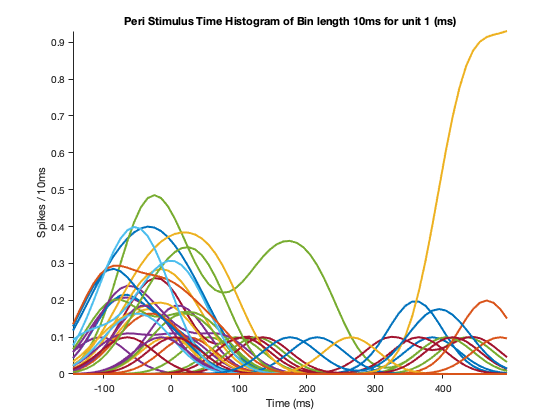



%   D)

%psth for unit 1
figure;
hold on;
for i = 1:totalConditions
 
    
    newPsth(smoothedAverageData(:,i,1), bins, 650, 1, 0);
    
end
hold off;

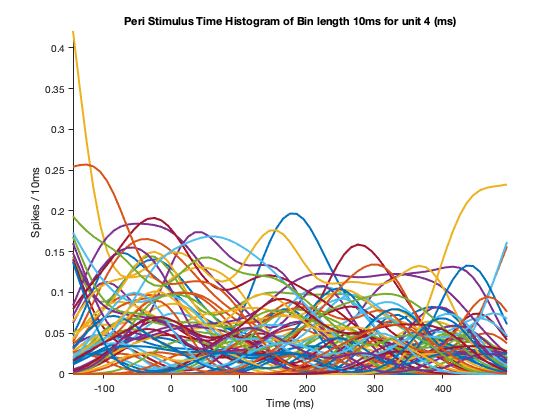


%psth for unit 4
figure;
hold on;
for i = 1:totalConditions
 
    
    newPsth(smoothedAverageData(:,i,4), bins, 650, 4, 0);
    
end
hold off;

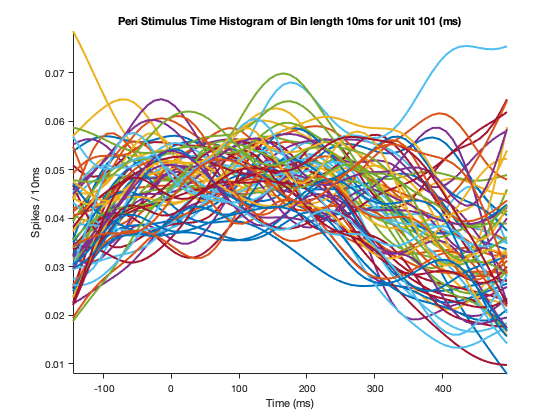


%psth for unit 101
figure;
hold on;
for i = 1:totalConditions
 
    
    newPsth(smoothedAverageData(:,i,101), bins, 650, 101, 0);
    
end
hold off;

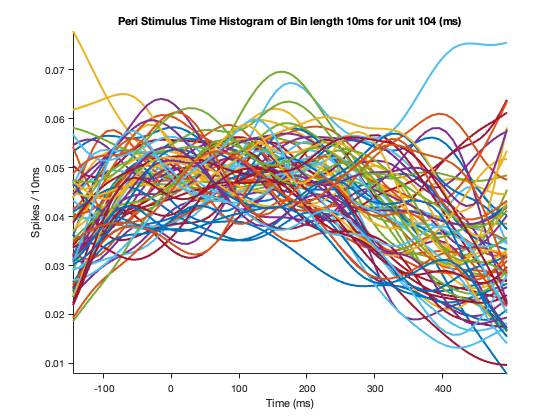


%psth for unit 104
figure;
hold on;
for i = 1:totalConditions
 
    
    newPsth(smoothedAverageData(:,i,102), bins, 650, 104, 0);
    
end
hold off;

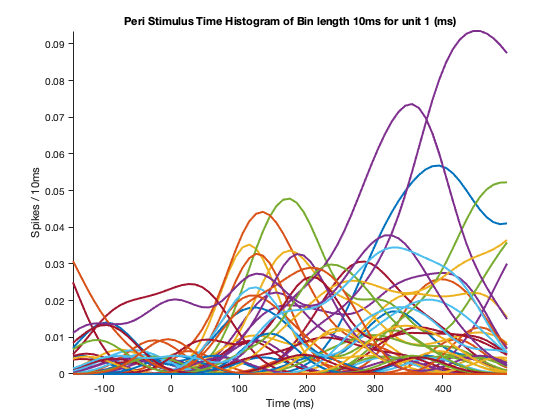


smoothedAllSpikes = gaussFilt1(allSpikes, sdMS, 1);

%   D) correct

%psth for unit 1
figure;
hold on;
for i = 1:totalConditions
 
    
    newPsth(smoothedAllSpikes(:,i,1), bins, 650, 1, 0);
    
end
hold off;

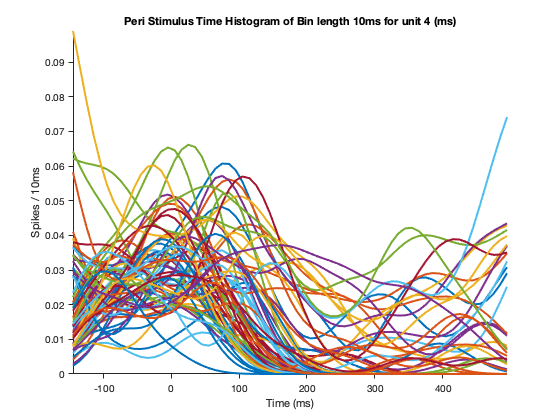


%psth for unit 4
figure;
hold on;
for i = 1:totalConditions
 
    
    newPsth(smoothedAllSpikes(:,i,4), bins, 650, 4, 0);
    
end
hold off;

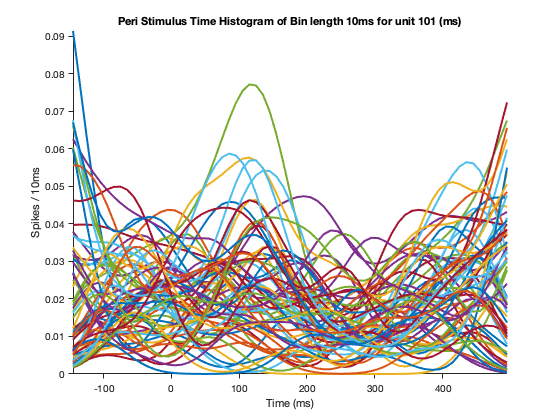


%psth for unit 101
figure;
hold on;
for i = 1:totalConditions
 
    
    newPsth(smoothedAllSpikes(:,i,101), bins, 650, 101, 0);
    
end
hold off;

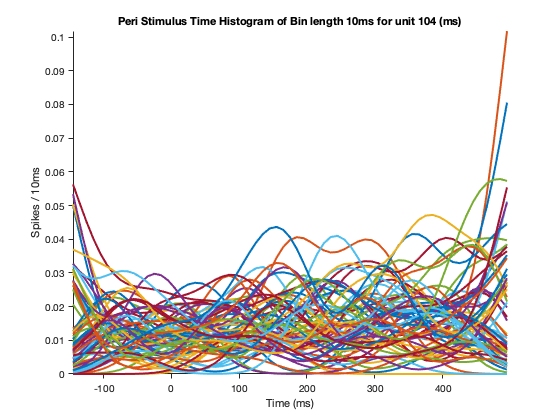


%psth for unit 104
figure;
hold on;
for i = 1:totalConditions
 
    
    newPsth(smoothedAllSpikes(:,i,102), bins, 650, 104, 0);
    
end
hold off;

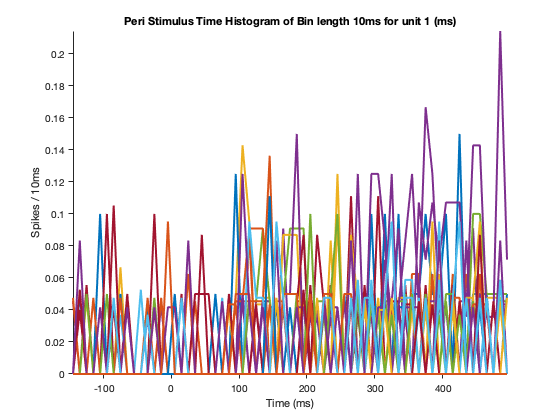

%   D) correct

%psth for unit 1
figure;
hold on;
for i = 1:totalConditions
 
    
    newPsth(allSpikes(:,i,1), bins, 650, 1, 0);
    
end
hold off;

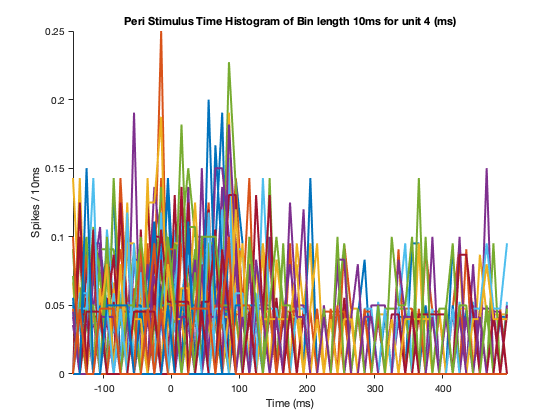


%psth for unit 4
figure;
hold on;
for i = 1:totalConditions
 
    
    newPsth(allSpikes(:,i,4), bins, 650, 4, 0);
    
end
hold off;

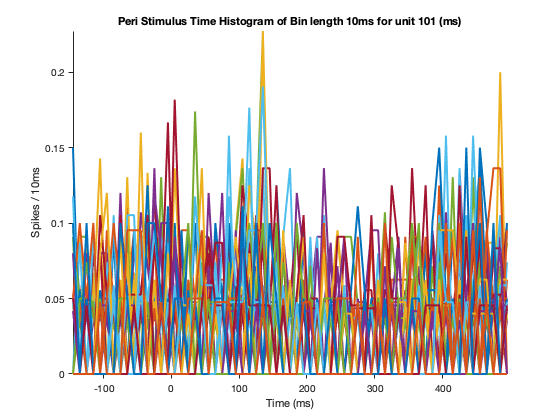


%psth for unit 101
figure;
hold on;
for i = 1:totalConditions
 
    
    newPsth(allSpikes(:,i,101), bins, 650, 101, 0);
    
end
hold off;

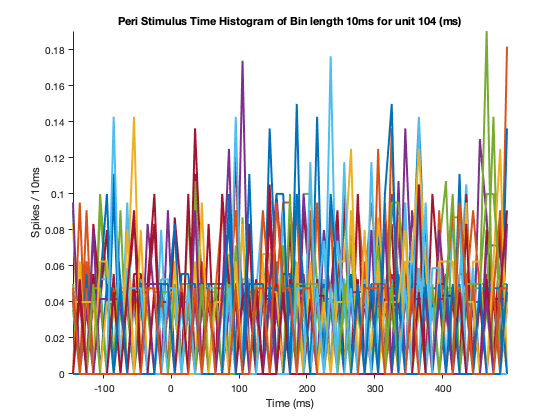


%psth for unit 104
figure;
hold on;
for i = 1:totalConditions
 
    
    newPsth(allSpikes(:,i,102), bins, 650, 104, 0);
    
end
hold off;

%C correct
[~, sortOrder] = sort([R.conditionID]);
conditionSortedR = R(sortOrder);

uniqueConditions = unique([conditionSortedR.conditionID]');
totalConditions = size(uniqueConditions, 1);


allSpikes = zeros(timeBins,totalConditions,units);


for conditionNum = 1:totalConditions
    
    currentCondition = uniqueConditions(conditionNum);
    conditionData = R([R.conditionID] == currentCondition);
    currentConditionSize = size(conditionData, 2);
    justSpikes = zeros(timeBins,currentConditionSize,units);
    

    
    for conditionTrialIndex = 1:currentConditionSize
            
            conditionTrialOnsetTime = conditionData(conditionTrialIndex).targetAppearsTime;
            conditionSpikesPerBin = [];
            
            for conditionUnitNum = 1:units
                
                conditionSpikesRelativeToMove = conditionData(conditionTrialIndex).unit(conditionUnitNum).spikeTimes - conditionTrialOnsetTime;
                conditionSpikesPerBin =  histcounts(conditionSpikesRelativeToMove, bins);
                
              
                justSpikes(:, conditionTrialIndex,conditionUnitNum) = conditionSpikesPerBin';
              
    
            end 
    end
    
    avgJustSpike =  mean(justSpikes, 2);
                
    allSpikes(:,conditionNum,:) = avgJustSpike;

            
end





%Part 2
%   A)
%want to reorganize data so that all observations from the 337 trials are
%put into one large matrix. All the colums refer to a kinematic type
%variable and the rows refer to all the observations taken among trials.

trialAveragedAs2D = reshape(trialAveragedData, [(timeBins * totalConditions) units]);

Unrecognized function or variable 'trialAveragedData'.

normalized2D = zeros(size(trialAveragedAs2D));
for i = 1:units
    columnRange = range(trialAveragedAs2D(:,i)) + 5;
    normalized2D(:,i) = trialAveragedAs2D(:,i) ./ columnRange;
end



[coeff ,score , latent] = pca(normalized2D);

usedCoeff = coeff(:,1:6);
usedScore = score(:,1:6);


figure;
hold on;
normalizedLatent = latent./sum(latent);
plot(normalizedLatent(1:20),'-ko', 'MarkerSize', 5, 'LineWidth', 1);
axis square;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('Principal Component'); 
ylabel('Explained Variance (0-1)');
title('Variance Explained by Principle Components');
hold off;

%There is an elbow


%Part 1
%   B)


figure;
hold on;
subplot(3, 2, 1)
coeff1Magnitudes = sort(usedCoeff(:,1),'ascend','ComparisonMethod','abs');

Unrecognized function or variable 'usedCoeff'.

stem(coeff1Magnitudes);
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('Unit'); 
ylabel('Loading Value');
title('Loading Values PC1');

subplot(3, 2, 2)
coeff2Magnitudes = sort(usedCoeff(:,2),'ascend','ComparisonMethod','abs');
stem(coeff2Magnitudes);
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('Unit'); 
ylabel('Loading Value');
title('Loading Values PC2');


subplot(3, 2, 3)
coeff3Magnitudes = sort(usedCoeff(:,3),'ascend','ComparisonMethod','abs');
stem(coeff3Magnitudes);
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('Unit'); 
ylabel('Loading Value');
title('Loading Values PC3');


subplot(3, 2, 4)
coeff4Magnitudes = sort(usedCoeff(:,4),'ascend','ComparisonMethod','abs');
stem(coeff4Magnitudes);
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('Unit'); 
ylabel('Loading Value');
title('Loading Values PC4');

subplot(3, 2, 5)
coeff5Magnitudes = sort(usedCoeff(:,5),'ascend','ComparisonMethod','abs');
stem(coeff5Magnitudes);
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('Unit'); 
ylabel('Loading Value');
title('Loading Values PC5');


subplot(3, 2, 6)
coeff6Magnitudes = sort(usedCoeff(:,6),'ascend','ComparisonMethod','abs');
stem(coeff6Magnitudes);
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('Unit'); 
ylabel('Loading Value');
title('Loading Values PC6');

sgtitle('PC 1-6 Loading Values Relative to Each Other');
hold off;

%The loadings generally seem to be dense in PCs 2,3, and 4; while having more 
% sparseness in 1, 5, and 6. The majority of values in most PCs hovers 
% around less than 0.1 though. In PCs 1,3,5, and 6, there seems to
%be a slight uptick in sparseness with the last quarter of values, being
%largest in magnitude, and around .1 or greater away from 0. Dimensions 2
%and 4 seem to slightly differ from the others in that they almost all of
%their values are close to 0, and they have just a few high magnitude
%loadings that are significantly far from 0, by about 0.4-0.6. This may be
%attributed to the level of variance explained by the the PCs relative to
%each other. 
% 
% The first PC, which should explain the most of the variance
% between the original variables, looks the smoothest and has the greatest
% overall magnitude (area unde curve) because it accounts for some decent
% explanation of all of the original variables, more than any other PC.

%Other PCs become more specialized in which of the original variables they
%explain best. PC 2 is really good at explaining some aspect of the last 10 
% or so units with their large coefficents while PC4 shows some other aspect among the last 
% 10 units in its negative space and PC3 can explain some other aspect of the last 25ish variables in
% negative space pretty well. Where sparseness does arrive, like the positive and negative
%clusters found among PC5 and PC6, it demonstrates that those PCs account
%for some apsect that is localized to small groups of units in those
%clusters that have similar transformations done to them as they enter PC
%space.


%   C)

smoothedTrialsAs2D = reshape(smoothedNeuralData, [(timeBins * trials) units]);

Unrecognized function or variable 'smoothedNeuralData'.

smoothNormalized2D = zeros(size(smoothedTrialsAs2D));
for j = 1:units
    smoothColumnRange = range(smoothedTrialsAs2D(:,j)) + 5;
    smoothNormalized2D(:,i) = smoothedTrialsAs2D(:,j) ./ smoothColumnRange;
end



[smoothCoeff ,smoothScore , smoothLatent] = pca(smoothNormalized2D);

usedSmoothCoeff = smoothCoeff(:,1:6);
usedSmoothScore = smoothScore(:,1:6);



%   D)
factorAnalysisSmooth = factoran(smoothedTrialsAs2D, 6);

Unrecognized function or variable 'smoothedTrialsAs2D'.

%   E)

[thetaSMFA,varargoutSMFA] = subspacea(factorAnalysisSmooth,smoothCoeff);
[thetaSMCO,varargoutSMCO] = subspacea(smoothCoeff,usedCoeff);
[thetaCOFA,varargoutCOFA] = subspacea(factorAnalysisSmooth,usedCoeff);

figure;
stem(thetaSMFA, 'c');
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('Principle Angle Index');
ylabel('Principle Angles (radians)');
title('Principle Angle between Factor Analysis and Simple PCA');

figure;
stem(thetaSMCO, 'm');
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('Principle Angle Index');
ylabel('Principle Angles (radians)');
title('Principle Angle between Simple PCA and Trial Averaged PCA');

figure;
stem(thetaCOFA, 'g');
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('Principle Angle Index');
ylabel('Principle Angles (radians)');
title('Principle Angle between Factor Analysis and Trial Averaged PCA');


%This shows that the principle angles between simple and trial averaged PCA
%is 0, the principle angles between simple PCA and factor analysis is
%nearly 0. And the principle angles between factor analysis and trial
%average PCAs is between .5-1.5 radians. The pair of spaces most similar
%are the trial averaged and simple pcas. This is because they are both pcas
%done of the same data set and are able to capture variance between
%varaibles in nearly the same way.

%The reason that factor analysis is closer to the simple pca than the trial
%averaged pca is due to the effects on noise of trial averaging. Factor
%analysis includes a measure of noise for the variables anf that noise is
%also expected to be present in the simple pca. The trial averaged pca does
%not have this noise however due to noise being cancelled out among trials
%that are averaged.
